# GLM

## Implementation following Neuromatch tutorials

[https://compneuro.neuromatch.io/tutorials/W1D3_GeneralizedLinearModels/student/W1D3_Tutorial1.html](https://compneuro.neuromatch.io/tutorials/W1D3_GeneralizedLinearModels/student/W1D3_Tutorial1.html)

%% Loading data and padding stimulus
start_stim = P.OFF_dur *P.fs;
stop_stim = (P.OFF_dur +P.ON_dur) * P.fs - 2*P.fs;

response = P(1).gcfr(:,start_stim:stop_stim);
stimulus = -P(1).antennal_movement(:,start_stim:stop_stim);



## Padding stimulus matrix


stim_window = 0.03;
stimRows = (size(stimulus,2)) %*P.no_of_trials;

stimRows = 160001

stimPatterns = zeros([stimRows stim_window*P.fs]);
spikeCol = zeros([stimRows 1]);
patternIdx  = 1;

paddedStim = [repelem(mean(stimulus,2), 1,stim_window*P.fs-1) stimulus];
paddedResponse = [zeros(size(response,1),stim_window*P.fs-1) response];


%% Generating design matrix and spike column 
for i=1%:P.no_of_trials
    for j=1:size(paddedStim,2)-stim_window*P.fs
        stimPatterns(patternIdx,:) = paddedStim(i, j:j+stim_window*P.fs-1);
        spikeCol(patternIdx) = paddedResponse(i,j+stim_window*P.fs-1);
        patternIdx=patternIdx+1;
    end
    
end

stimPatterns = [ones(stimRows,1) stimPatterns];


## Without padding

stim_window = 0.03;
stimRows = (size(stimulus,2))%*P.no_of_trials;
stimPatterns = zeros([stimRows stim_window*P.fs]);
spikeCol = zeros([stimRows 1]);
patternIdx  = 1;


%% Generating design matrix and spike column 
for i=1%:P.no_of_trials
    for j=1:size(stimulus,2)-stim_window*P.fs
        stimPatterns(patternIdx,:) = stimulus(i, j:j+stim_window*P.fs-1);
        spikeCol(patternIdx) = response(i,j+stim_window*P.fs-1);
        patternIdx=patternIdx+1;
    end
    
end

## Generating Gaussian linear model

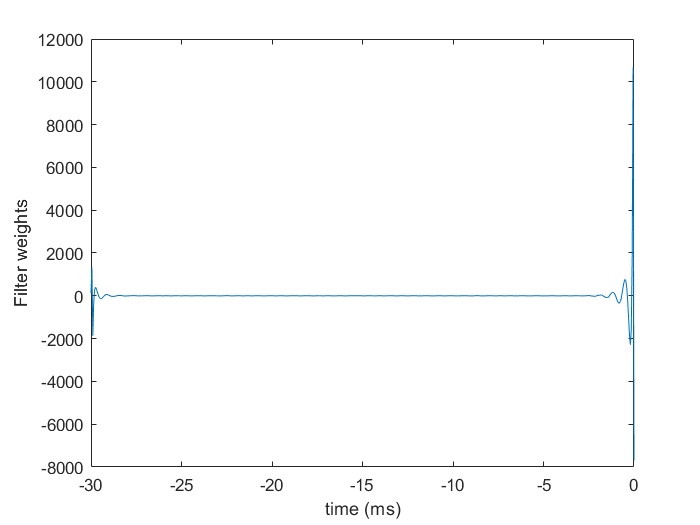

theta = (stimPatterns'*stimPatterns)\stimPatterns'*spikeCol;
t = linspace(-30,0,length(theta));
figure;
plot(t,theta);
ylabel('Filter weights');
xlabel('time (ms)')

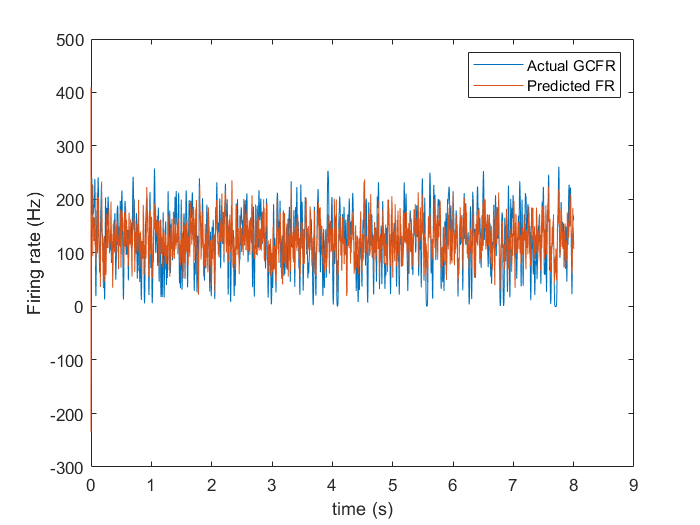


responseFit = stimPatterns*theta;
figure;
plot(linspace(0, length(stimulus)/P.fs, length(stimulus)), P.gcfr(1,start_stim:stop_stim)); 
hold on;
plot(linspace(0, length(stimulus)/P.fs, length(stimulus)), responseFit);
xlabel('time (s)');
ylabel('Firing rate (Hz)');
legend('Actual GCFR', 'Predicted FR');

% mdl = fitglm(stimPatterns,spikeCol,'linear','Distribution',"normal")
